# Filtros digitales

Un filtro digital clásico se puede definir como un sistema que modifica una señal digital de manera que deja pasar un determinado intervalo de frecuencias y atenúa otras con el objetivo de obtener una salida con unas características determinadas. Los filtros “clásicos” trabajan en el espacio frecuencial y se diseñan en este espacio.

Concretamente, estudiaremos los filtros digitales realizables por lo cual deben verificar las siguientes propiedades:

- Linealidad, 

- Invariancia en el tiempo

- Causalidad 

- Estabilidad.

## Caracteristicas de un filtro: respuesta al impulso y funcion de transferencia

Un filtro, genéricamente hablando, es un sistema que **discrimina parte del objeto que procesa**, según uno o más atributos. Por ejemplo, un **filtro de aire** deja pasar el aire pero impide el paso a las partículas  de polvo presentes en el aire.

Tipos clásicos de filtro:

- Pasa bajo.

- Pasa alto.

- Pasa banda.

- Elimina banda.

"AGREGAR IMAGENES DE LOS TIPOS DE FILTROS IDEALES"

Respecto a la fase, un filtro ideal tiene la fase lineal. Esto significa que la fase de la respuesta del filtro es una función lineal de la frecuencia. Por lo tanto, la señal filtrada no tiene distorsión de fase.

- **Pasa bajos**

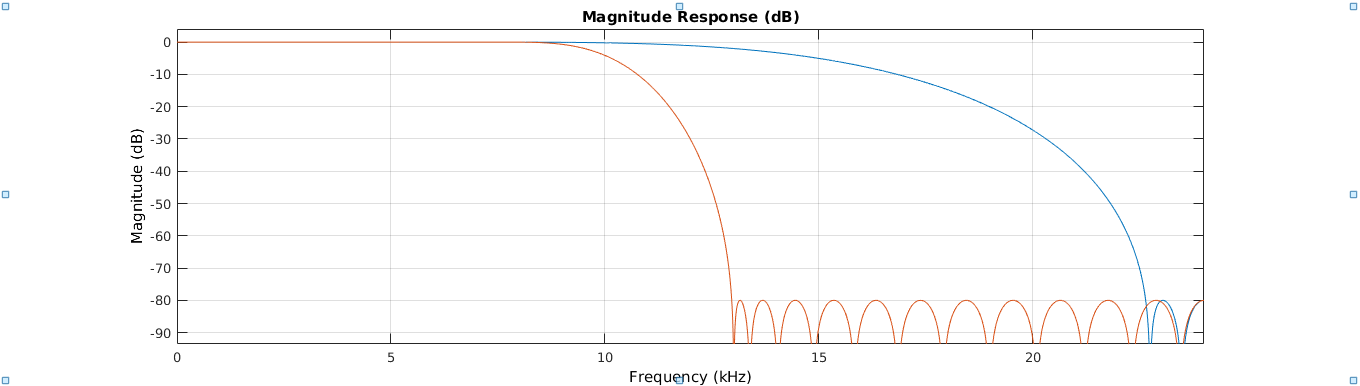

N1 = 10; % numero de orden
N2 = 40;
Fs = 48e3; % frecuencia de muestreo
Fp = 8e3; % frecuencia de corte
Ap = 0.01; % ripple en la banda de paso
Ast = 80; % atenuacion de la banda eliminada

Rp  = (10^(Ap/20) - 1)/(10^(Ap/20) + 1); % maxima desviacion de la banda de paso
Rst = 10^(-Ast/20); % maxima desviacion de la banda eliminada

NUM1 = firceqrip(N1,Fp/(Fs/2),[Rp Rst],'passedge'); % filtro FIR equiripple (Algoritmo Parks-McClellan)
NUM2 = firceqrip(N2,Fp/(Fs/2),[Rp Rst],'passedge');

fvt = fvtool(NUM1,1,NUM2,1,'Fs',Fs,'Color','White');

legend(fvt,'FIltro FIR - Orden = 100','FIltro FIR - Orden = 200')


- **Pasa altos**

N1 = 10; % numero de orden
N2 = 40;
Fs = 48e3; % frecuencia de muestreo
Fp = 8e3; % frecuencia de corte
Ap = 0.01; % ripple en la banda de paso
Ast = 80; % atenuacion de la banda eliminada

Rp  = (10^(Ap/20) - 1)/(10^(Ap/20) + 1); % maxima desviacion de la banda de paso
Rst = 10^(-Ast/20); % maxima desviacion de la banda eliminada

NUM1 = firceqrip(N1,Fp/(Fs/2),[Rp Rst],'passedge'); % filtro FIR equiripple (Algoritmo Parks-McClellan)
NUM2 = firceqrip(N2,Fp/(Fs/2),[Rp Rst],'passedge');

fvt = fvtool(NUM1,1,NUM2,1,'Fs',Fs,'Color','White');